1

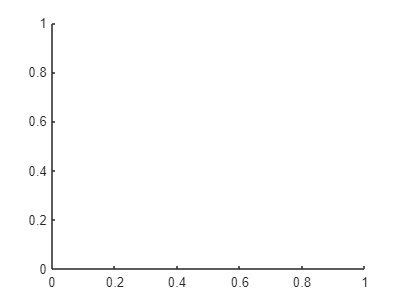

Unrecognized function or variable 'OST'.

Error in Blatt6>voreu (line 77)
        [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));

delta_t_range = [0.1 0.2 0.4];
startx = 0;
endx = 2;
phi0 = 0;
for delta_t=delta_t_range
    figure()
    hold on
    [t, p] = voreu(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = ruckeu(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = trapez(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    t = 0:0.01:2;
    p = real_phi(t);
    plot(t,p,'--k')
    legend('Vorwärts-Euler','Rückwärts-Euler','Trapezregel','exakt')
    title(strcat('delta t:', string(delta_t)))
end

2

delta_t_range = [0.1 0.2 0.4];
startx = 0;
endx = 2;
phi0 = 0;
for delta_t=delta_t_range
    figure()
    hold on
    [t, p] = voreu(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = ruckeu(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = trapez(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = ab2(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = am3(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    [t, p] = bdf2(@dphi,delta_t,startx,endx,phi0);
    plot(t,p)
    t = 0:0.01:2;
    p = real_phi(t);
    plot(t,p,'--k')
    legend('Vorwärts-Euler','Rückwärts-Euler','Trapezregel','AB2','AM3','BDF2','exakt')
    title(strcat('delta t:', string(delta_t)))
    if delta_t == 0.4
        ylim([0 9e-3]);
    else
        ylim([0 4e-3]);
    end
end

function f = real_phi(t)
    f = exp(-5.*t).*(t.^2-2.*t+2)-2.*exp(-6.*t);
end

function f = dphi(t, phit)
    f = t^2*exp(-5*t)-6*phit;
end

function num = M(t)
    num = 1;
end

function num = B(t)
    num = -6;
end

function num = C(t)
    num = t^2*exp(-5*t);
end

function [t, f] = voreu(df, delta_t, startx, endx, f0)
    t = startx:delta_t:endx;
    f = zeros(size(t));
    f(1) = f0;
    for i=1:numel(t)-1
%         f(i+1) = f(i) + delta_t*df(t(i),f(i));
        theta = 0;
        [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));
        f(i+1) = LHS\RHS;
    end
end

function [t, f] = ruckeu(df, delta_t, startx, endx, f0)
    t = startx:delta_t:endx;
    f = zeros(size(t));
    f(1) = f0;
    for i=1:numel(t)-1
        theta = 1;
        [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));
        f(i+1) = LHS\RHS;
    end
end

function [t, f] = trapez(df, delta_t, startx, endx, f0)
    t = startx:delta_t:endx;
    f = zeros(size(t));
    f(1) = f0;
    for i=1:numel(t)-1
        theta = 0.5;
        [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));
        f(i+1) = LHS\RHS;
    end
end

function [t, f] = ab2(df, delta_t, startx, endx, f0)
    t = startx:delta_t:endx;
    f = zeros(size(t));
    f(1) = f0;
    for i=1:numel(t)-1
        if i==1
            theta = 0.5;
            [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));
        else
            [LHS,RHS] = AB2(delta_t,M(t(i)),[B(t(i)) B(t(i-1))],[C(t(i)) C(t(i-1))],[f(i) f(i-1)]);
        end
        f(i+1) = LHS\RHS;
    end
end

function [t, f] = am3(df, delta_t, startx, endx, f0)
    t = startx:delta_t:endx;
    f = zeros(size(t));
    f(1) = f0;
    for i=1:numel(t)-1
        if i==1
            theta = 0.5;
            [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));
        else
            [LHS,RHS] = AM3(delta_t,M(t(i)),[B(t(i+1)) B(t(i)) B(t(i-1))],[C(t(i+1)) C(t(i)) C(t(i-1))],[f(i) f(i-1)]);
        end
        f(i+1) = LHS\RHS;
    end
end

function [t, f] = bdf2(df, delta_t, startx, endx, f0)
    t = startx:delta_t:endx;
    f = zeros(size(t));
    f(1) = f0;
    for i=1:numel(t)-1
        if i==1
            theta = 0.5;
            [LHS,RHS] = OST(theta,delta_t,M(t(i)),[B(t(i+1)) B(t(i))],[C(t(i+1)) C(t(i))],f(i));
        else
            [LHS,RHS] = BDF2(delta_t,M(t(i)),[B(t(i+1))],[C(t(i+1))],[f(i) f(i-1)]);
        end
        f(i+1) = LHS\RHS;
    end
end
